clear;

tic;

## 初始参数定义，能量尺度，采点数，单层格子数，在位能，跃迁能等

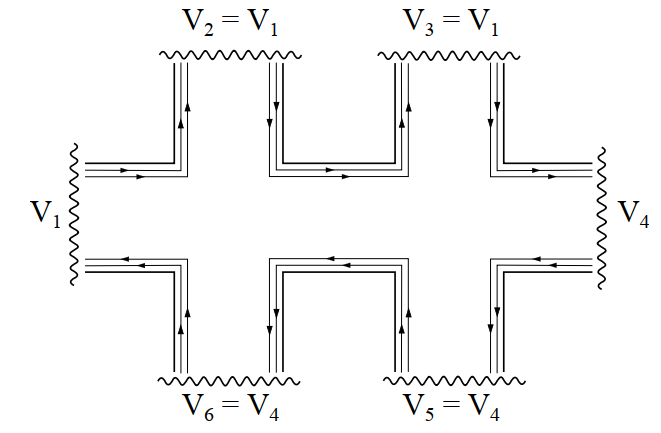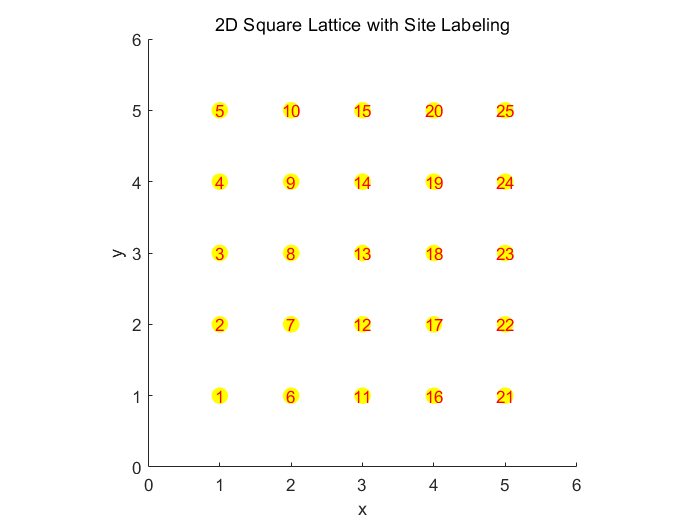

为简便起见，定义载流子为空穴，此时要形成图示电流需加垂直面内的磁场$-B\hat{z}$

从而矢势可以写为$\hat{A} =\left(B\;y,0,0\right)$


omega = -3.5;
% omega = linspace(-4,4,21);
fermilevel = -3.5;
p = 1;
q = 17;
% number of unitcell in one layer
Width = 20;
% onsite energy
epsilon_0 = 0;
Length = 3*Width;
% hopping
t = 1;

% infinitesimal parameter
eta = 1e-6;

% 迭代次数
Accuracy = 1e-10;

% Magnetic field
N_phi = 21;
phi = linspace(0,0.25,N_phi);
% phi = 0;
% phi = 0.1716;
% Inverse matrix
Iden_Central = eye(Length * Width);
% 无序度
Disorder = 0.1;
Boundary_Condition = "PBC";

% 端口标号
N_terminal = 6;
Terminal = cell(N_terminal,1);
for ii = 1:N_terminal
    Terminal{ii} = terminal_label(ii, Length, Width);
end
PlotBand = false;

#### 能带部分

if PlotBand
    kx_step = 201;
    
    phi = 2*pi*p/q;
    
    kx = [0,2*pi];
    ky = pi / (2*q);
    kx_list = linspace(kx(1), kx(2),kx_step);
    
    energy_band = zeros(kx_step, Width);
    for jj = 1:length(phi)
        for ii = 1:length(kx_list)
            energy_band(ii, :) = eig(Hamiltonian_2D_Momentum(kx_list(ii), ky, Width, epsilon_0, phi(jj), t, Boundary_Condition));
        end
        plot(kx_list-phi/2,energy_band, kx_list, fermilevel*ones(1,length(kx_list)),'--');
        title(['phi=',num2str(phi(jj))])
        % pause(.01)
    end
    xlabel('k_x-\phi/2')
    ylabel('E')
    title(['Energy band with \phi=',num2str(phi)])
end





量子霍尔效应部分

Conductance = zeros(N_terminal, N_terminal);
Resistance_Longi = zeros(length(phi), length(omega));
Resistance_Hall = zeros(length(phi), length(omega));
for ii = 1:length(phi)
    disp(ii)

    % toc;
    % intralayer hopping
    H_00 = epsilon_0 * eye(Width) - t * diag(ones(1,Width-1),1) - t*diag(ones(1, Width-1),-1);
    % interlayer hopping, Landau gauge A = (By, 0,0) = (B*a*n,0,0)
    H_01 = -t * diag(exp(1i * (1:Width) * phi(ii)));
    for mm = 1:length(omega)

        % Wire's Selfenergy calculation
        G_Wire_Surface = SurfaceGreenFunction_V2_mex(H_00, H_01, omega(mm), Accuracy);

        % Self energy matrices
        Sigma = cell(N_terminal,1);
        % Longitudinal lead
        Sigma{1} = SurfaceGreenFunction_SelfEnergy(G_Wire_Surface, H_01);
        Sigma{4} = Sigma{1}.';

        % Transverse Lead 2 and 3
        H_Lead_2 = -t * diag(exp(1i * (1:Width) * (Width+1)*phi(ii)));
        % H_Lead_2 = -t * eye(Width);
        Sigma{2} = SurfaceGreenFunction_SelfEnergy(G_Wire_Surface, H_Lead_2);
        Sigma{3} = Sigma{2};

        % Transverse Lead 5 and 6
        H_Lead_5 = -t * eye(Width);
        Sigma{5} = SurfaceGreenFunction_SelfEnergy(G_Wire_Surface, H_Lead_5);
        Sigma{6} = Sigma{5};

        % Central area hamiltonian
        H_CC = Hamiltonian_2D_Real(Length, Width, phi(ii), -t);
        H_CC = H_CC + Disorder * spdiags(rand(Length * Width,1) - 0.5,0,Length * Width,Length * Width);

        Sigma_Extend = zeros(Length * Width);
        % Gamma = zeros(N_terminal, Length * Width, Length * Width);
        Gamma = cell(N_terminal,1);

        % 计算端口时需要扩张端口的自能矩阵到整个哈密顿量
        for jj = 1:N_terminal
            Sigma_Extend(Terminal{jj},Terminal{jj}) = Sigma{jj};
            temp = zeros(Length * Width);
            temp(Terminal{jj},Terminal{jj}) = SurfaceGreenFunction_Broadening(Sigma{jj});
            Gamma{jj} = sparse(temp);
        end
        % tic;
        % G_Centre_Ret = sparse(((omega(mm)+1i*eta)*Iden_Central - H_CC - Sigma_Extend)\Iden_Central);
        G_Centre_Ret = inv((omega(mm)+1i*eta)*speye(Length*Width) - H_CC - sparse(Sigma_Extend));
        toc;
        % 计算端口-端口的电导矩阵元
        % 最大开销，大矩阵相乘，如何优化?
        for jj = 1: N_terminal
            temp_1 = Gamma{jj} * G_Centre_Ret;
            for kk = 1: N_terminal
                if jj ~= kk
                    temp_2 = temp_1 * Gamma{kk};
                    % Conductance(jj, kk, ii, mm) = -real(trace(temp_2 * G_Centre_Ret'));
                    Conductance(jj, kk) = -real(trace(temp_2 * G_Centre_Ret'));
                    % Conductance(jj, kk, ii, mm) = -real(GreenFunction_Transmission(temp_1, temp_2, G_Centre_Ret));
                end
            end
        end
        % for jj = 1: N_terminal
        %     Conductance(jj, jj, ii, mm) = sum(-Conductance(jj,:,ii,mm));
        % end
        Conductance = Conductance - diag(sum(Conductance));

        % Calculate the hall conductance for 6 terminal setup
        Conductance_22 = Conductance([1,4],[1,4]);
        Conductance_24 = Conductance([1,4],[2,3,5,6]);
        Conductance_42 = Conductance([2,3,5,6],[1,4]);
        Conductance_44 = Conductance([2,3,5,6],[2,3,5,6]);
        % add voltage to the 1-4 port
        V_14 = [1;0];
        Voltage_2356 = -(Conductance_44 \ Conductance_42) * V_14;
        Current_14 = (Conductance_22-Conductance_24 * (Conductance_44 \ Conductance_42)) * V_14;
        Resistance_Longi(ii, mm) = (Voltage_2356(1) - Voltage_2356(2))/Current_14(1);
        Resistance_Hall(ii, mm) = (Voltage_2356(1) - Voltage_2356(4))/Current_14(1);
    end
end

     1



历时 0.285772 秒。


     2



历时 0.877774 秒。


     3



历时 1.422502 秒。


     4



历时 1.950630 秒。


     5



历时 2.503365 秒。


     6



历时 3.046763 秒。


     7



历时 3.585934 秒。


     8



历时 4.140770 秒。


     9



历时 4.674878 秒。


    10



历时 5.216834 秒。


    11



历时 5.759259 秒。


    12



历时 6.304361 秒。


    13



历时 6.843109 秒。


    14



历时 7.379680 秒。


    15



历时 7.916215 秒。


    16



历时 8.459837 秒。


    17



历时 9.058586 秒。


    18



历时 9.603017 秒。


    19



历时 10.155805 秒。


    20



历时 10.716974 秒。


    21



历时 11.256473 秒。


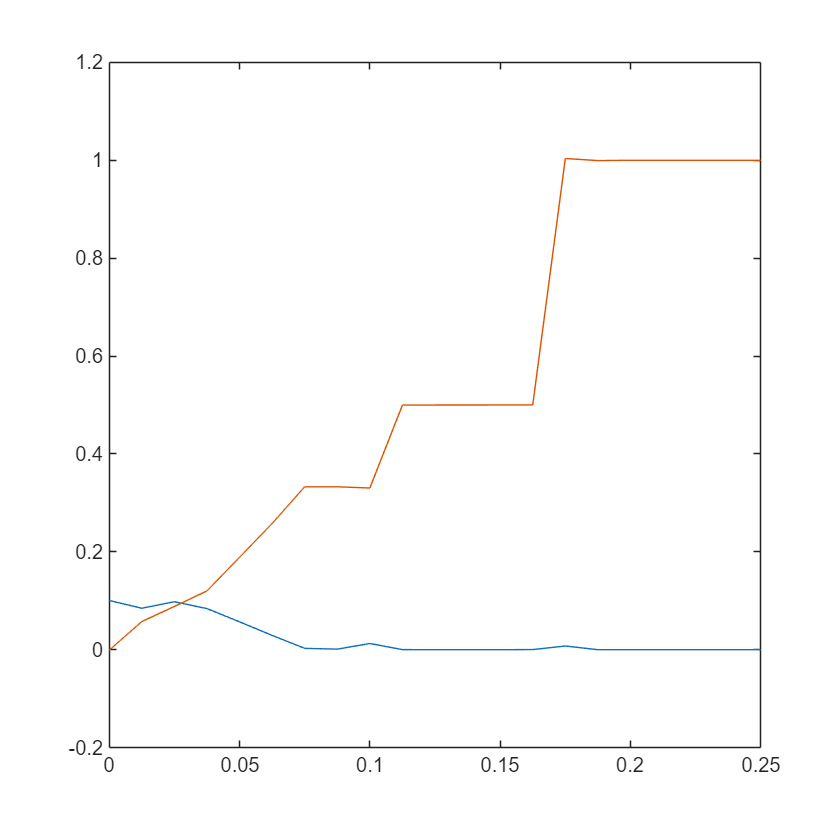


plot(phi, Resistance_Longi,phi,Resistance_Hall)

% plot(omega, Resistance_Longi,phi,Resistance_Hall)

% 辅助函数
toc;

历时 11.643314 秒。


function H = Hamiltonian_2D_Real(Length, Width, phi, t)

% H_00 = epsilon * eye(Width) - t * diag(ones(1, Width-1),1) - t * diag(ones(1, Width-1),-1);
% H_01 = -t * diag(exp(1i * (1:Width) * phi));
%
% H = kron(eye(Length), H_00) + kron(diag(ones(1, Length-1),1), H_01) + kron(diag(ones(1, Length-1),-1), H_01');
%
H = get_Nearest_Square_Hopping_Sparse_V2(Width, Length, t, t, [], "Bx", phi);
% H = full(get_Nearest_Square_Hopping_Sparse(Width, Length, t, t, [], phi));
end

function H = Hamiltonian_2D_Momentum(kx, ky, Width, epsilon, phi, t, varargin)

H_00 = epsilon * eye(Width) - t * exp(1i * ky) * diag(ones(1, Width-1),1) - t * exp(-1i * ky) *diag(ones(1, Width-1),-1);
H_01 = -t * diag(exp(1i * (0:Width-1) * phi));

if nargin > 6
    if varargin{1} == "PBC"
        H_00(1, end) = exp(-1i * ky);
        H_00(end, 1) = exp(1i * ky);
    end
end
H = H_00 + exp(1i * kx) * H_01 + exp(-1i * kx) * H_01';

end

function sitelabel = sitelabel(x,y,Width)
sitelabel = (x-1) * Width + y;

end

function label = terminal_label(terminal, Length, Width)
Distance_Boundary = 2;
switch terminal

    case 1
        label = 1:Width;

    case 2
        label = sitelabel(Distance_Boundary,Width,Width) :Width:sitelabel(Distance_Boundary+Width-1,Width,Width);

    case 3
        label = sitelabel(Length-Width-Distance_Boundary+2,Width,Width) :Width: sitelabel(Length-Distance_Boundary+1,Width,Width);
    case 4
        label = ((Length * Width)-Width+1):(Length * Width);
    case 5

        label = sitelabel(Length-Width-Distance_Boundary+2,1,Width) :Width:sitelabel(Length-Distance_Boundary+1,1,Width);
    case 6

        label = sitelabel(Distance_Boundary,1,Width) :Width:sitelabel(Distance_Boundary+Width-1,1,Width);

end
end
